% Second order transfer function with zero on LHS

## STEP -1 : Make a 2nd order Transfer Function

%Recall the generic form of the second order transfer function
% H(s) = wn^2/(s^2 + 2*zeta*wn*s + wn^2)
%For illsutration let us assume 
wn = 1; % Any value > 0 can be taken and 
zeta = 0.7; % i.e. and underdamped system (can take zeta = 1 or zeta > 1 also)

## Step 1 : TF with no zeros

NUM_a = wn*wn; DEN_a = [1 2*zeta*wn wn*wn];
H_a = tf(NUM_a,DEN_a);
P_a = pole(H_a);
Z_a = zero(H_a);

## Step 2: Add zero on RHS

zr = -1 ; % Location of zero is -5
NUM_b = [wn*wn/zr wn*wn]; % Zero is added
DEN_b = DEN_a;
H_b = tf(NUM_b,DEN_b);
P_b = pole(H_b);
Z_b = zero(H_b);

## Step 3: Step Response

Ha_step = step(H_a);
Hb_step = step(H_b);

## Step 3- Plot and compare responses

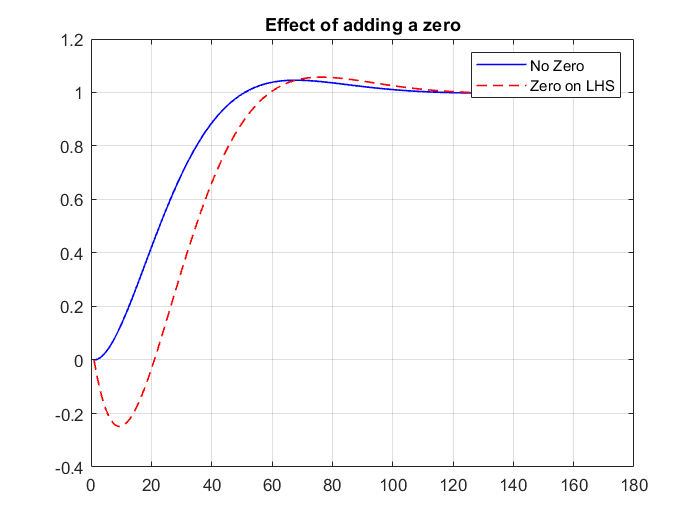

figure;plot(Ha_step,'-b','LineWidth',1); hold on;plot(Hb_step,'--r','LineWidth',1);
grid on;
legend('No Zero','Zero on LHS')
title('Effect of adding a zero');



% Ex: Check for influence of varying pole locations on the step response
% (Hint: vary zr locations on the RHS)